## **Worked Example 10.2**

 AERO60007 Control Systems 2024-2025

% Housekeeping
clear
clc
close all

% Input the dynamics matrix and calculate its eigenvalues
A = [0 1 0 0; 3 0 0 2; 0 0 0 1; 0 -2 0 0];
eig(A)

ans =    0.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i
   0.0000 + 0.0000i


jordan(A)

ans =    0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i



% Input the remaining matrices and create a state-space system
B = [0 0; 1 0; 0 0; 0 1];
C = [1 0 0 0; 0 0 1 0];
D = [0];
sys = ss(A, B, C, D);


% Create a vector of the desired eigenvalue locations 
P = [-1; (-1 + 3i); (-1 - 3i); -1];

% Calculate the state feedback gain vector K
K = -1 * place(A, B, P)

K =    -3.0000   -1.0000    1.0000   -1.0000
  -10.0000   -8.0000   -2.0000   -3.0000



% Compute the feedforward gain 𝑘𝑟 
kr = -inv (C * inv (A + B * K) * B) 

kr =     0.0000   -1.0000
   10.0000    2.0000



% Create a vector of the desired observer error eigenvalue locations 
P_e = [-10; (-10 + 30i); (-10 - 30i); -10];

% Calculate the observer feedback gain vector L
L = place(A', C', P_e)'

L =    19.0968   -6.7253
  296.4524  -45.4463
  101.2422   20.9032
  994.2285  122.4825


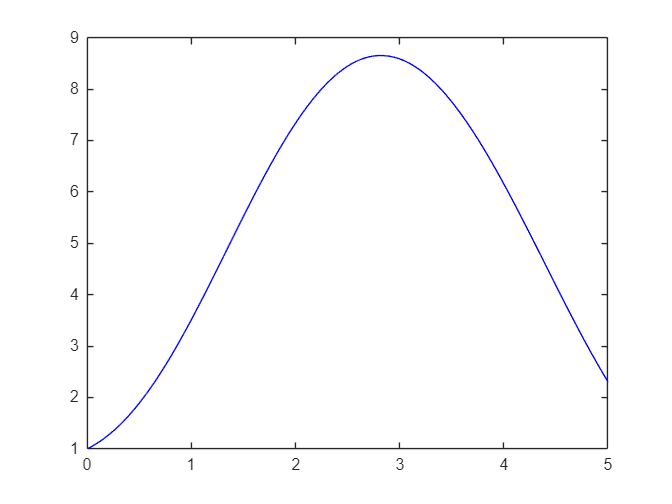

% Create the closed-loop state-space systemr
A_cl = [(A + B * K) (-B * K); zeros(size(A)) (A - L * C)];
B_cl = [B * kr; zeros(size(B))];
C_cl = [C zeros(size(C))];
D_cl = [0];
sys_cl = ss(A_cl, B_cl, C_cl, D_cl);

% Create the time input and input force vctors
T = [0 : 0.001 : 5]';
U = [exp(-T) .* sin(2 * T) exp(-T) .* sin(3 * T)];

% Set the initial conditions for the open-loop system 
x0 = [1; 1; 0; 0]; 

% Set the initial conditions for the closed-loop system 
z0 = [1; 1; 0; 0; 1; 1; 0; 0];

% Simulate and store the open-loop response Y and the states Z at each time-step T
[Y_o, T_o, X] = lsim(sys, U, T, x0);

% Plot the evolution of the open-loop states 
plot(T_o, X(:,1),'-b') 

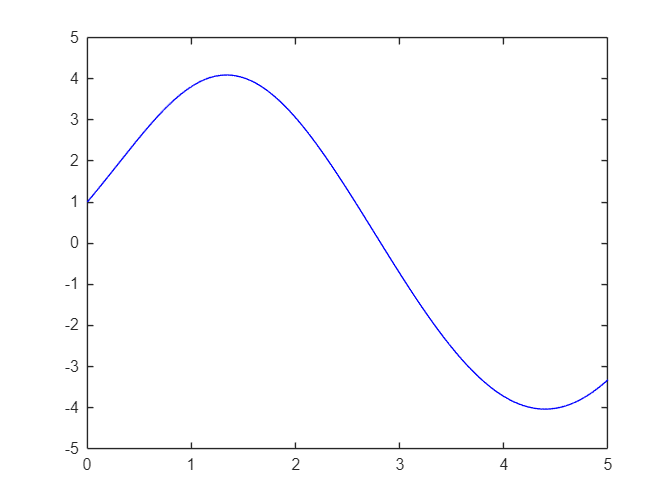

plot(T_o, X(:,2),'-b') 

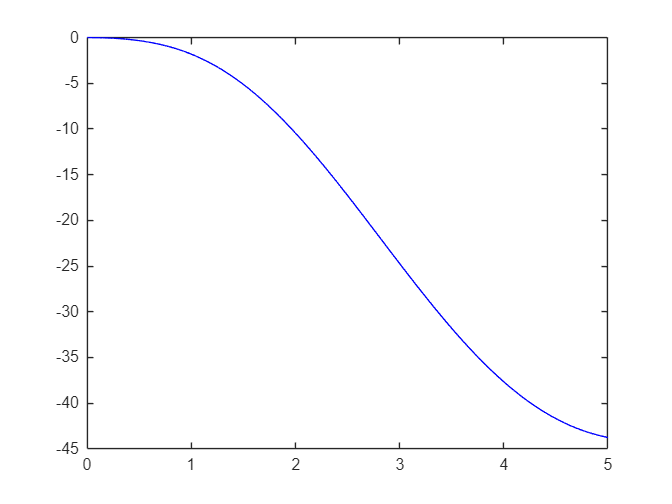

plot(T_o, X(:,3),'-b') 

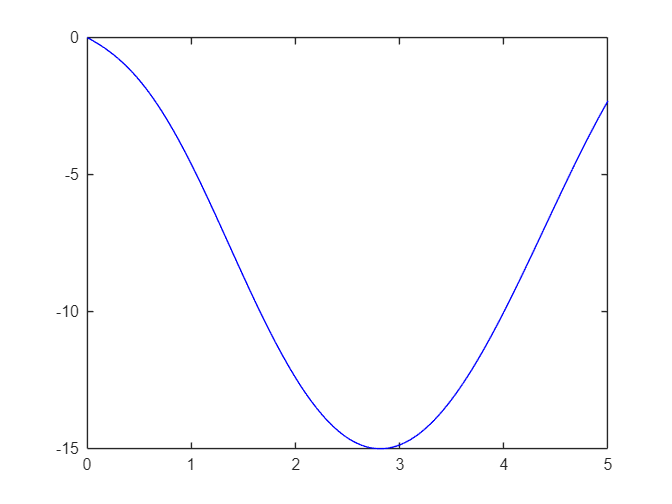

plot(T_o, X(:,4),'-b')

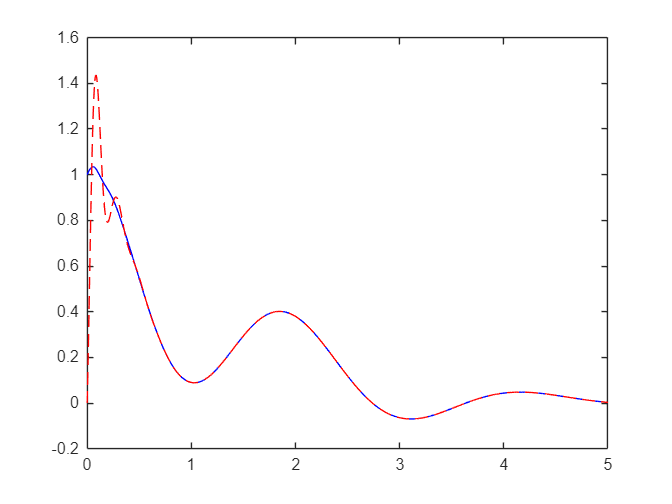


% Simulate and store the closed-loop response Y and the states Z at each time-step T
[Y,T,Z] = lsim(sys_cl, U, T, z0); 

% Plot the evolution of the states along with their observer estimates 
plot(T, Z(:,1),'-b', T, (Z(:,1)-Z(:,5)),'--r') 

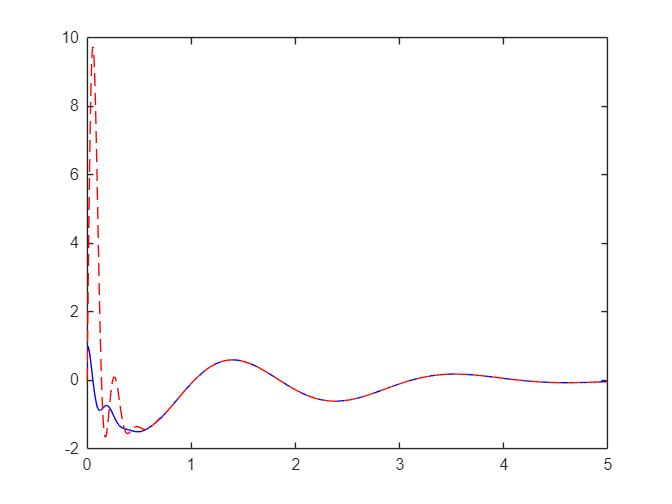

plot(T, Z(:,2),'-b', T, (Z(:,2)-Z(:,6)),'--r') 

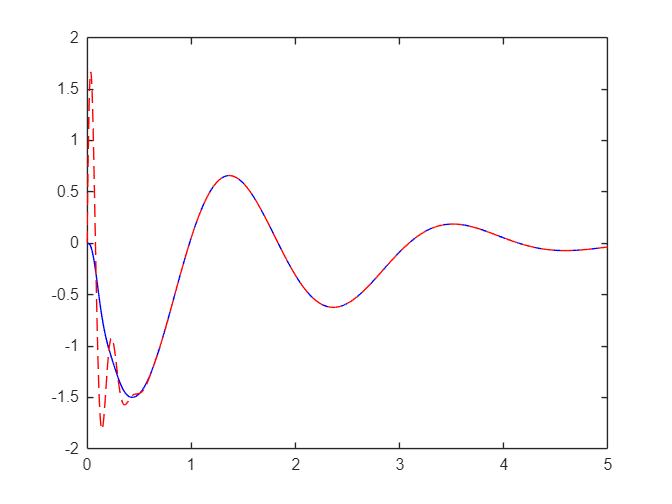

plot(T, Z(:,3),'-b', T, (Z(:,3)-Z(:,7)),'--r') 

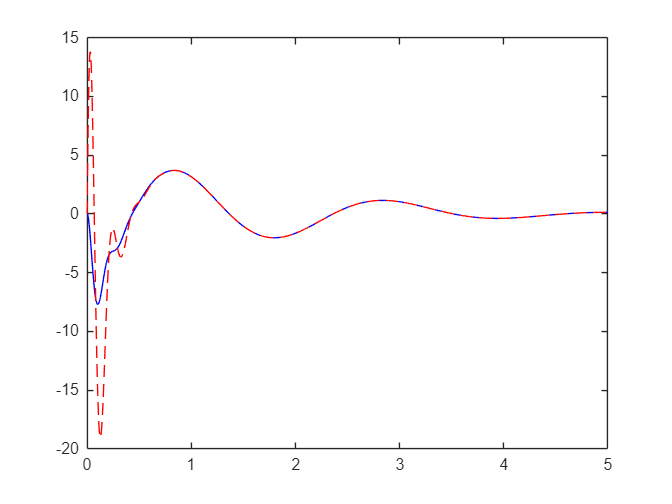

plot(T, Z(:,4),'-b', T, (Z(:,4)-Z(:,8)),'--r')